# Irradiance 1D

clear;
close all;
[param, weather, route, driver] = loadData();

## Time domain

### Sunrise and sunset estimator

interestDay = datetime(2020,10,20);

startDriving_8 = datetime(year(interestDay), month(interestDay), day(interestDay),8,0,0);
stopDriving_17 = datetime(year(interestDay), month(interestDay), day(interestDay),17,0,0);

bef15minSunrise = weather.irradiance1D.bef15minSunrise.datetime(day(interestDay));
sunrise = weather.irradiance1D.sunrise.datetime(day(interestDay));
sunset = weather.irradiance1D.sunset.datetime(day(interestDay));
aft15minSunset = weather.irradiance1D.aft15minSunset.datetime(day(interestDay));

sunriseChargeDuration = startDriving_8 - bef15minSunrise;
sunsetChargeDuration = aft15minSunset - stopDriving_17;

increaseSoCmorning = chargeEstimator(bef15minSunrise, startDriving_8)

increaseSoCmorning = 0.0515

increaseSoCafternoon = chargeEstimator(stopDriving_17, aft15minSunset)

increaseSoCafternoon = 0.0286

#### Plot

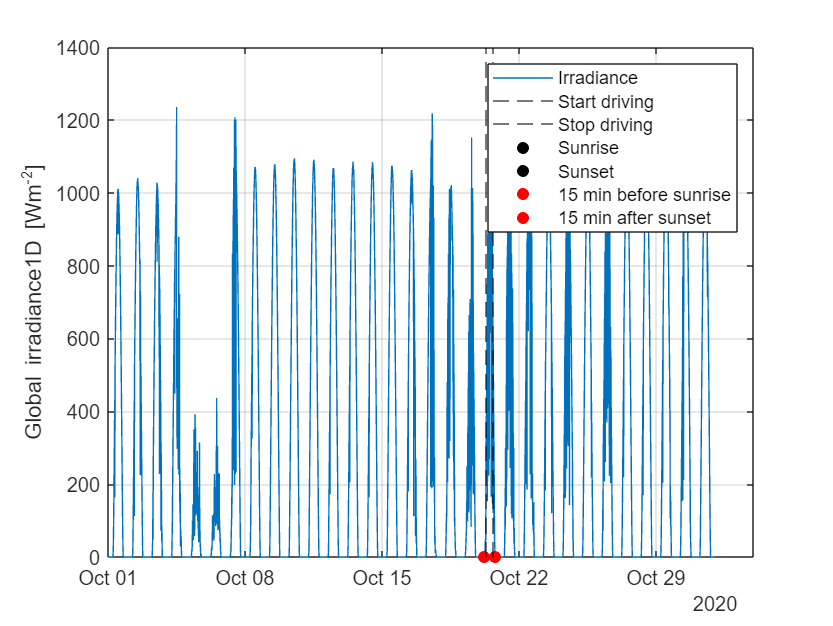

fun = @(t) weather.irradiance1D.Gtotal(find(weather.irradiance1D.time == t),1);

figure
hold on
plot(weather.irradiance1D.time, weather.irradiance1D.Gtotal, 'DisplayName', 'Irradiance')
xline(startDriving_8, 'k--', 'DisplayName', 'Start driving')
xline(stopDriving_17, 'k--', 'DisplayName', 'Stop driving')
scatter(sunrise, fun(sunrise), 'k','filled', 'DisplayName', 'Sunrise')
scatter(sunset, fun(sunset), 'k','filled', 'DisplayName', 'Sunset')
scatter(bef15minSunrise, fun(bef15minSunrise), 'r','filled', 'DisplayName', '15 min before sunrise')
scatter(aft15minSunset, fun(aft15minSunset), 'r','filled', 'DisplayName', '15 min after sunset')
ylabel("Global irradiance1D [Wm^{-2}]")
legend()
clickableLegend
box on
grid on
hold off

## Space domain

### 30 minute stops

stopDuration = minutes(30);
initialTime = datetime(2020,10,18,14,10,0);
finalTime = initialTime + stopDuration;

increaseSoC = chargeEstimator(initialTime, finalTime)

increaseSoC = 0.0722

## Tokai comparison

initialTimeTokai = weather.irradiance1DTokai.time(1);
finalTimeTokai = weather.irradiance1DTokai.time(end);
morningStartTokai = datetime(year(initialTimeTokai), month(initialTimeTokai), day(initialTimeTokai),8,0,0);
afternoonStopTokai = datetime(year(initialTimeTokai), month(initialTimeTokai), day(initialTimeTokai),17,0,0);

increaseSoCmorningTokai = chargeEstimatorTokai(initialTimeTokai, morningStartTokai)

increaseSoCmorningTokai = 0.0806


increaseSoCafternoonTokai = chargeEstimatorTokai(afternoonStopTokai, finalTimeTokai)

increaseSoCafternoonTokai = 0.0911

#### Plot

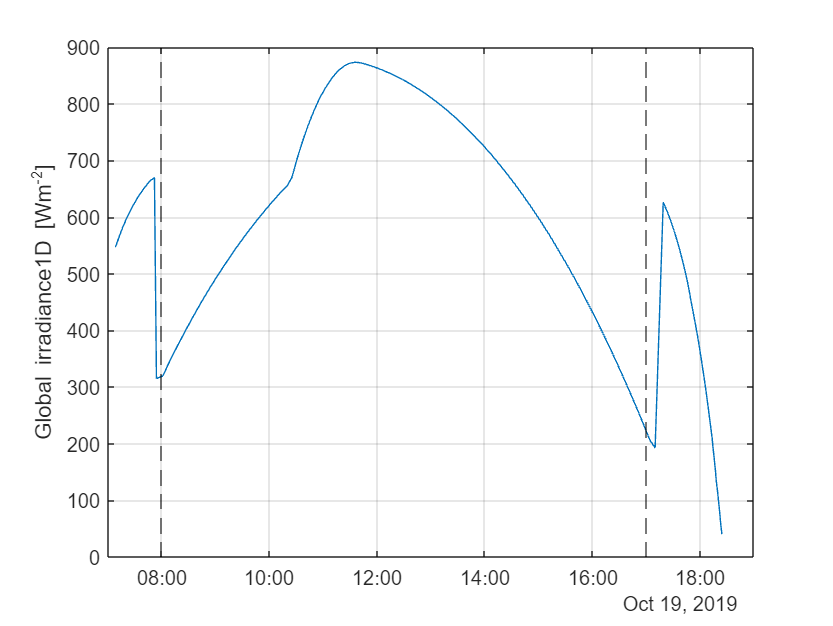

figure
plot(weather.irradiance1DTokai.time, weather.irradiance1DTokai.Gtotal)
xline(morningStartTokai, 'k--')
xline(afternoonStopTokai, 'k--')
ylabel("Global irradiance1D [Wm^{-2}]")
box on
grid on